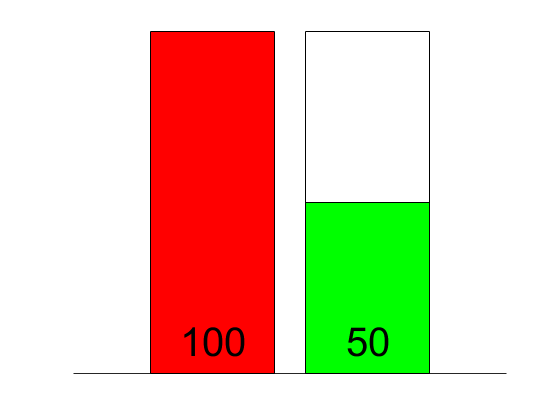

clear;

X = categorical({'Brake','Throttle'});

brake = 100;
throttle = 50;
inputs = [brake throttle];

c = bar(X,[100,100],'FaceColor','flat');
c(1).CData = [1 1 1; 1 1 1];

hold on

b = bar(X,inputs,'FaceColor','flat');
b.YDataSource = 'inputs';

b(1).CData = [1 0 0; 0 1 0];
ylim([0 100])
ax = gca;
disableDefaultInteractivity(ax)
axis off

xtips2 = b(1).XEndPoints;
ytips2 = [10 10];
labels2 = string(b(1).YData);
label = text(xtips2,ytips2,labels2,'HorizontalAlignment','center','FontSize',30);


% for i = 1:100
%     inputs = [i 100-i];
%     refreshdata
%     drawnow
%     pause(1/60);
%     delete(label);
%     labels2 = string(b(1).YData);
%     label = text(xtips2,ytips2,labels2,'HorizontalAlignment','center','FontSize',30);
% end

hold off;

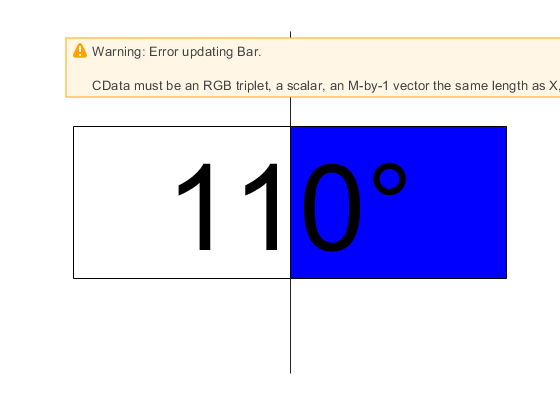


steering = 0;

X2 = categorical({'Steering'});
h0 = barh(X2,110,'FaceColor','flat');
h0(1).CData = [1 1 1];

hold on

h1 = barh(X2,-110,'FaceColor','flat');
h1(1).CData = [1 1 1];

hold on

h = barh(X2,steering,'blue');
h.YDataSource = 'steering';
xlim([-110 110])
ax = gca;
disableDefaultInteractivity(ax)
axis off
steeringLabel = text(1,0,num2str(steering),'HorizontalAlignment','center');

for i = -110:110
    %tic
    steering = i;
    refreshdata
    drawnow
    %pause(1/6000);
    %t(i) = toc;
    delete(steeringLabel);
    steeringLabel = text(0,1,[num2str(steering) '°'],'HorizontalAlignment','center','VerticalAlignment','middle','FontSize',90);
end

hold off


plot(t)

Unrecognized function or variable 't'.

function updateData
    
end


%b(2).CData = [0 0 1];
